path = uigetdir;

images = path + "\images";
masks = path + "\masks";

imdsTrain = imageDatastore(images,"ReadFcn",...
            @(x)imresize(rgb2gray(imread(x)),[256,256]));numClasses = 2;
classes = ["zp","bg"];
labels = [1 0];
pxdsTrain = pixelLabelDatastore(masks,classes,labels,"ReadFcn",@(x)im2bw(imresize(imread(x),[256 256])));

imgg = readimage(imdsTrain,89)

imgg = 256×256 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

tbl = countEachLabel(pxdsTrain);
numberPixels = sum(tbl.PixelCount);

frequency = tbl.PixelCount/numberPixels;
classWeights = 1 ./ frequency;

numFiles = numel(imdsTrain.Files); % Total files in train datastore
indices = randperm(numFiles); % Random indices for each file 

% Define the ratios for splitting
trainRatio = 0.7;
validationRatio = 0.2;
testRatio = 0.1;

numTrain = round(trainRatio * numFiles);  % = 144 files for training
numVal = round(validationRatio * numFiles); % =41 files for validation
numTest = numFiles - numTrain - numVal; % =20 files for testing our CNN

% Split the indices into training, validation, and test sets
trainIndices = indices(1:numTrain); % first 144 elements of the indices matrix for the 144 files, 1x144
valIndices = indices(numTrain+1:numTrain+numVal); % 41 (144th-185th) elements of the indices matrix for the 41 files 
testIndices = indices(numTrain+numVal+1:end); % 20 (186th - 205th) elements.....

% Correspond each index to each png image
imdsTrainSplit = subset(imdsTrain, trainIndices);
imdsValSplit = subset(imdsTrain, valIndices);
imdsTestSplit = subset(imdsTrain, testIndices);

pxdsTrainSplit = subset(pxdsTrain, trainIndices);
pxdsValSplit = subset(pxdsTrain, valIndices);
pxdsTestSplit = subset(pxdsTrain, testIndices);

% Combine images and labels for each dataset
dsTrain = combine(imdsTrainSplit, pxdsTrainSplit);
dsVal = combine(imdsValSplit, pxdsValSplit);
dsTest = combine(imdsTestSplit, pxdsTestSplit);

netlayers=[ 
    imageInputLayer([256 256 1]);
%--1d
    convolution2dLayer(3, 32, 'Padding', 'same');
    batchNormalizationLayer;
    reluLayer();
    maxPooling2dLayer(2, 'Stride', 2);
%--2d
    convolution2dLayer(3, 128, 'Padding', 'same');
    batchNormalizationLayer;
    reluLayer('Name', 'relu2conv');
    maxPooling2dLayer(2, 'Stride', 2);
%--3d
    convolution2dLayer(3, 128, 'Padding', 'same');
    batchNormalizationLayer;
    reluLayer('Name', 'relu3conv');%<==== concatenate to 3u
    maxPooling2dLayer(2, 'Stride', 2);
%--4d
    convolution2dLayer(3, 512, 'Padding', 'same');
    batchNormalizationLayer;
    reluLayer();
    maxPooling2dLayer(2, 'Stride', 2);
%------- Expanding path
%--4u
    transposedConv2dLayer([2 2], 512, 'Stride', 2);
    batchNormalizationLayer; 
    reluLayer();
    
%--3u
    transposedConv2dLayer([2 2], 128, 'Stride', 2);   
    concatenationLayer(3, 2, 'Name', 'concat3');%<========
%    convolution2dLayer(3, 128, 'Padding', 'same');
    batchNormalizationLayer;
    reluLayer();
%--2u
    transposedConv2dLayer([2 2], 128, 'Stride', 2);
    concatenationLayer(3, 2, 'Name', 'concat2');%<========
    
    batchNormalizationLayer;
    reluLayer();
%--1u
    transposedConv2dLayer([2 2], 32, 'Stride', 2);
    batchNormalizationLayer;
    reluLayer();

    convolution2dLayer(1, numClasses);

    softmaxLayer();
    pixelClassificationLayer('Classes', classes, 'ClassWeights', classWeights);
];

% Create layer graph
lgraph = layerGraph(netlayers);

% Connect relu3up to the second input of concat
lgraph = connectLayers(lgraph, 'relu3conv', 'concat3/in2');
% Connect relu3up to the second input of concat
lgraph = connectLayers(lgraph, 'relu2conv', 'concat2/in2');
% Analyze the network
analyzeNetwork(lgraph);

netlayers=lgraph;

options = trainingOptions('adam',...
    'InitialLearnRate',0.001,...
    'MaxEpochs',30,...
    'MiniBatchSize',25,...
    'Plots','training-progress',...
    'ValidationData',dsVal);

% netlayers = trainNetwork(dsTrain,netlayers,options);

% save('ZPnet.mat','netlayers');
load('ZPnet.mat','netlayers');

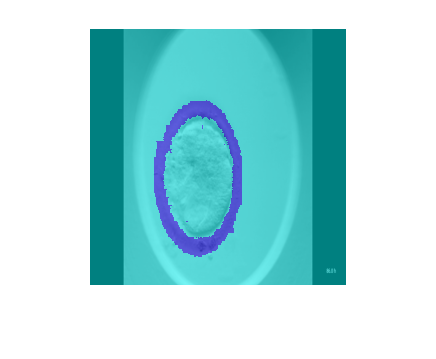

I = readimage(imdsTestSplit,3);
C = semanticseg(I,netlayers,Classes=classes);
B = labeloverlay(I,C);
imshow(B)

pxdsResults = semanticseg(dsTest,netlayers, ...
    Classes=classes, ...
    MiniBatchSize=4, ...
    WriteLocation=tempdir);

Running semantic segmentation network
-------------------------------------
* Processed 20 images.



metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTestSplit,Verbose=false);

dataSetMetrics = metrics.DataSetMetrics

dataSetMetrics = 1×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.98219          0.98787       0.85876      0.96901        0.86947  


classMetrics = metrics.ClassMetrics

classMetrics = 2×3 table
          Accuracy      IoU      MeanBFScore
          ________    _______    ___________

    zp    0.99419     0.73625      0.82075  
    bg    0.98156     0.98126      0.91819  


metrics.ImageMetrics

ans = 20×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

         0.978          0.97897       0.82417      0.96294        0.78713  
       0.98123           0.9891       0.85143      0.96764        0.85147  
       0.98314          0.98093       0.87328      0.96999        0.85948  
       0.98024          0.98932       0.84502      0.96619         0.8438  
         0.985          0.99153       0.87853       0.9734        0.92785  
       0.98431          0.98863       0.87371      0.97226        0.87534  
       0.98346          0.98957       0.86715      0.97098        0.88345  
       0.98367          0.99112       0.86887      0.97134        0.90887  
       0.98027          0.98904       0.84561      0

metrics.ConfusionMatrix

ans = 2×2 table
           zp          bg    
          _____    __________

    zp    65150           381
    bg    22958    1.2222e+06


metrics.NormalizedConfusionMatrix

ans = 2×2 table
             zp          bg   
          ________    ________

    zp     0.99419    0.005814
    bg    0.018437     0.98156
